% Author: Wei Zhou
% Institution: Department of Mechanical and Materials Engineering, 
% University of Cincinnati, Cincinnati, OH 45221, USA
% Year: 2022
% Version: 2.0
% Reference: Empirical Fourier decomposition: An accurate signal decomposition method
% for nonlinear and non-stationary time series analysis
% https://doi.org/10.1016/j.ymssp.2021.108155
% =========================================================================

**Signal generation**

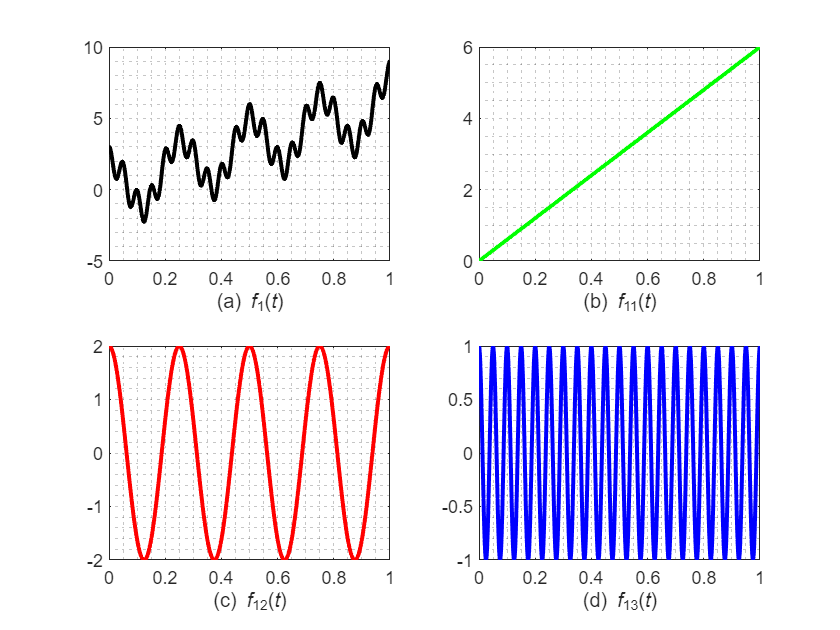

clear; clc; close all
set(0,'defaultlinelinewidth',2)
T = 1;          % total time
fs = 1000;      % sample frequency
t = (0:1/fs:T); % time step
f11 = 6*t;
f12 = 2*cos(8*pi*t);
f13 = cos(40*pi*t);
sig1 = f11+f12+f13;
% plot
figure
subplot(221)
plot(t,sig1,'k'); grid minor
set(gca,'XTick',(0:0.2:1))
xlabel('(a) \itf\rm_1(\itt\rm)')
subplot(222)
plot(t,f11,'g'); grid minor
set(gca,'XTick',(0:0.2:1))
xlabel('(b) \itf\rm_{11}(\itt\rm)')
subplot(223)
plot(t,f12,'r'); grid minor
set(gca,'XTick',(0:0.2:1))
xlabel('(c) \itf\rm_{12}(\itt\rm)')
subplot(224)
plot(t,f13,'b'); grid minor
set(gca,'XTick',(0:0.2:1))
xlabel('(d) \itf\rm_{13}(\itt\rm)')

**Using EFD to decompose**

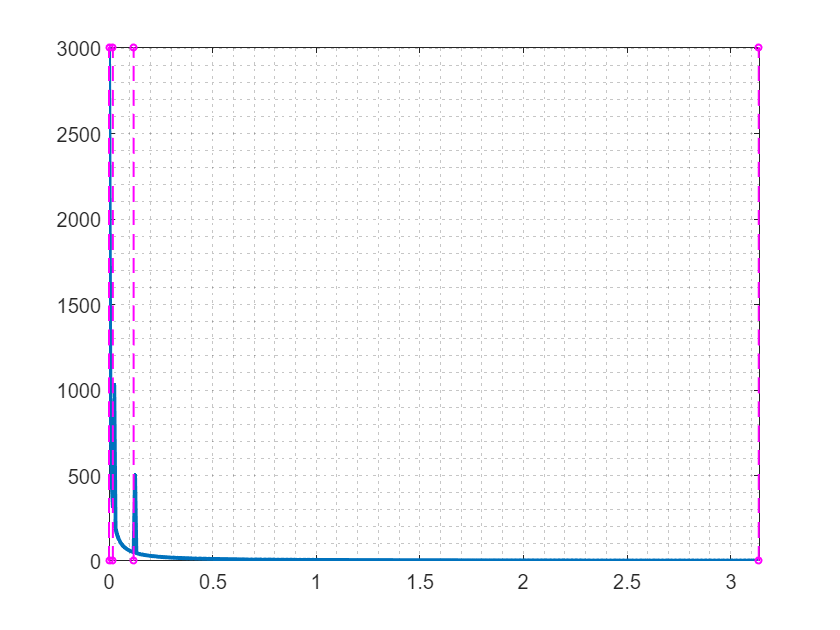

% the sig1 consists of 3 components, so 3 segments are needed
N = 3;
% perform EFD
[efd,cerf,boundaries] = EFD(sig1,N);
% plot the detected boundaries, to check the segmentation results
plotbounds(sig1,boundaries); grid minor

**Results**

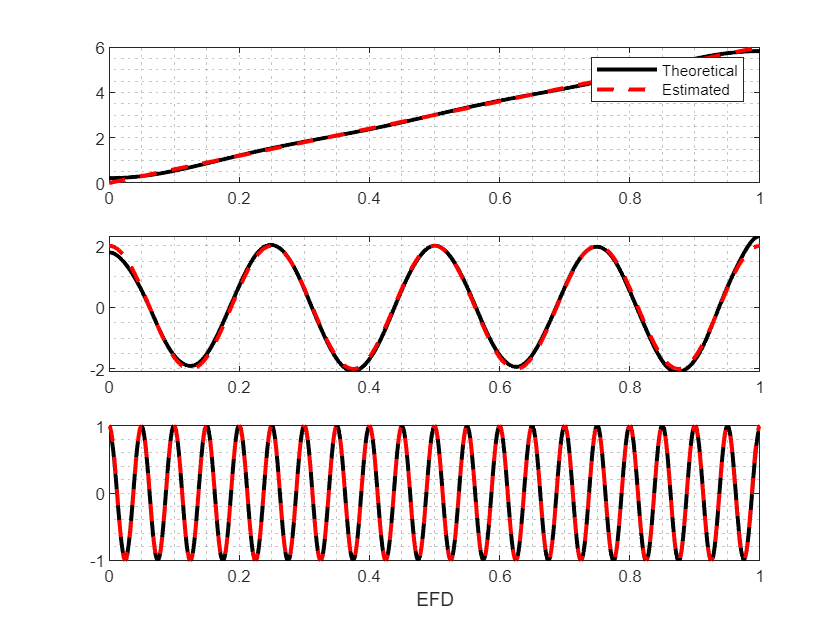

% three components
figure
subplot(3,1,1)
plot(t,efd{1,1},'k')
hold on 
plot(t,f11,'--r'); grid minor
set(gca,'XTick',(0:0.2:1))
legend('Theoretical','Estimated')
subplot(3,1,2)
plot(t,efd{2,1},'k'); grid minor
hold on 
plot(t,f12,'--r')
set(gca,'XTick',(0:0.2:1))
subplot(3,1,3)
plot(t,efd{3,1},'k'); grid minor
hold on 
plot(t,f13,'--r')
set(gca,'XTick',(0:0.2:1))
xlabel('EFD')